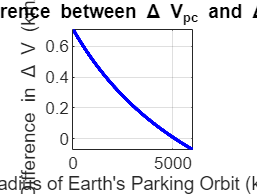

clear
clc

% Define parameters
mu_sun = 1.3271244e11;  % Gravitational parameter of the Sun (km^3/s^2)
mu_earth = 3.986e5;     % Gravitational parameter of Earth (km^3/s^2)
mu_mars = 4.2828e4;     % Gravitational parameter of Mars (km^3/s^2)
R_earth_sun = 1.4959787e8;  % Distance from the Sun to Earth (km)
R_mars_sun = 2.279391e8;    % Distance from the Sun to Mars (km)
r_p_mars = 3796;   % Radius of Mars' parking orbit (km)
a_t = (R_earth_sun + R_mars_sun) / 2;  % Example semi-major axis
R_earth = 6378;
R_mars = 3396; 

alt_range = 0:6000;
r_p_earth_vec = alt_range + R_earth;

% Initialize arrays to store results
dv_1_pc_array = zeros(1, length(alt_range));  % To store dv_1_pc values
dv_1_hm_array = zeros(1, length(alt_range));   % To store dv_1_hm values

% Loop over r_p_earth alt from 0 to 6000 km
for i = 1:length(r_p_earth_vec)
    r_p_earth = r_p_earth_vec(i);
    [dv_1_pc, ~, ~, ~] = ...
        patch_conic_transfer(mu_sun, mu_earth, mu_mars, R_earth_sun, R_mars_sun, r_p_earth, r_p_mars, a_t);
    
    [dv_1_hm, ~, ~, ~] = hohmann_transfer(R_earth_sun, R_mars_sun, mu_sun);
    
    % Store the results
    dv_1_pc_array(i) = dv_1_pc;  % Store dv_1_pc
    dv_1_hm_array(i) = dv_1_hm;   % Store dv_1_hm
end

% Calculate the difference between dv_1_pc and dv_1_hm
dv_1_dif = dv_1_pc_array - dv_1_hm_array;

% Create the plot
figure;
plot(alt_range, dv_1_dif, 'b-', 'LineWidth', 2);
xlabel("Radius of Earth's Parking Orbit (km)");
ylabel('Difference in \Delta V (km/s)');
title('Difference between \Delta V_{pc} and \Delta V_{hm}');
grid on;
axis square;

% Optionally, set x-axis limits
xlim([0 6000]);

leedle

clear
clc

% Define parameters
mu_sun = 1.3271244e11;  % Gravitational parameter of the Sun (km^3/s^2)
mu_earth = 3.986e5;     % Gravitational parameter of Earth (km^3/s^2)
mu_mars = 4.2828e4;     % Gravitational parameter of Mars (km^3/s^2)
R_earth_sun = 1.4959787e8;  % Distance from the Sun to Earth (km)
R_mars_sun = 2.279391e8;    % Distance from the Sun to Mars (km)
r_p_mars = 3796;   % Radius of Mars' parking orbit (km)
a_t = (R_earth_sun + R_mars_sun) / 2;  % Example semi-major axis
R_earth = 6378;
R_mars = 3396; 

alt_range = 0:6000;
r_p_earth_vec = alt_range + R_earth;

% Initialize arrays to store results
dv_1_pc_array = zeros(1, length(alt_range));  % To store dv_1_pc values
dv_1_hm_array = zeros(1, length(alt_range));   % To store dv_1_hm values

% Loop over r_p_earth alt from 0 to 6000 km
for i = 1:length(r_p_earth_vec)
    r_p_earth = r_p_earth_vec(i);
    [dv_1_pc, ~, ~, ~] = ...
        patch_conic_transfer(mu_sun, mu_earth, mu_mars, R_earth_sun, R_mars_sun, r_p_earth, r_p_mars, a_t);
    
    [dv_1_hm, ~, ~, ~] = hohmann_transfer(R_earth_sun, R_mars_sun, mu_sun);
    
    % Store the results
    dv_1_pc_array(i) = dv_1_pc;  % Store dv_1_pc
    dv_1_hm_array(i) = dv_1_hm;   % Store dv_1_hm
end